rosshutdown();

Shutting down global node /matlab_global_node_94214 with NodeURI http://192.168.178.112:57151/ and MasterURI http://192.168.178.125:11311.


setenv('ROS_MASTER_URI', 'http://192.168.178.125:11311');
setenv('ROS_IP', '192.168.178.112');
rosinit('192.168.178.125');

The value of the ROS_IP environment variable, 192.168.178.112, will be used to set the advertised address for the ROS node.
Initializing global node /matlab_global_node_63656 with NodeURI http://192.168.178.112:58203/ and MasterURI http://192.168.178.125:11311.


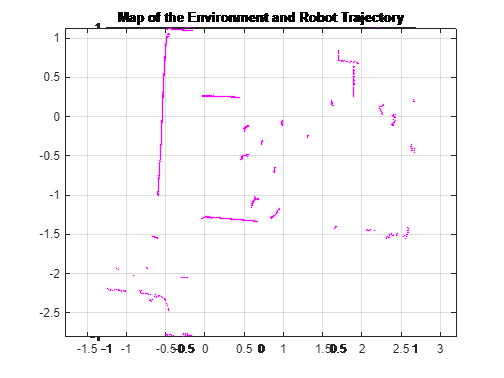


lidarSub = rossubscriber('/scan', 'sensor_msgs/LaserScan');
hFigMap = figure;

maxLidarRange = 12;
gridResolution = 20;

% Create lidarScanMap object

mapObj = lidarscanmap(gridResolution, maxLidarRange);
pGraph = poseGraph(mapObj);
xlimit = [-1, 1];
ylimit = [-1, 1];
while ishandle(hFigMap)
    
    % Receive LIDAR scan
    scans = receive(lidarSub, 2);
    range = double(scans.Ranges); % Convert Ranges to double
    angle = double(linspace(scans.AngleMin, scans.AngleMax, numel(range))); % Convert Angles to double
    scan = lidarScan(range, angle);

    % Add scan to the map
    map = addScan(mapObj, scan);
    if ~map
        disp("Scan could not be added to the map.");
        continue;
    end

    % Retrieve pose
    % updatePoseGraph(mapObj, pGraph, scan);
    poses = nodeEstimates(pGraph);
    

    % Plot map and trajectory
    axMap = axes(Parent=hFigMap);
    show(mapObj, Parent=axMap); % Show the map
    hold(axMap, 'on');
    plot(axMap, poses(:,1), poses(:,2), 'r', 'LineWidth', 2);
    plot(axMap, poses(:,1), poses(:,2), 'ro', 'MarkerSize', 4, 'MarkerFaceColor', 'r');
    hold(axMap, 'off');
    title(axMap, "Map of the Environment and Robot Trajectory");
    xlim(axMap, xlimit);
    ylim(axMap, ylimit);
    drawnow;
end